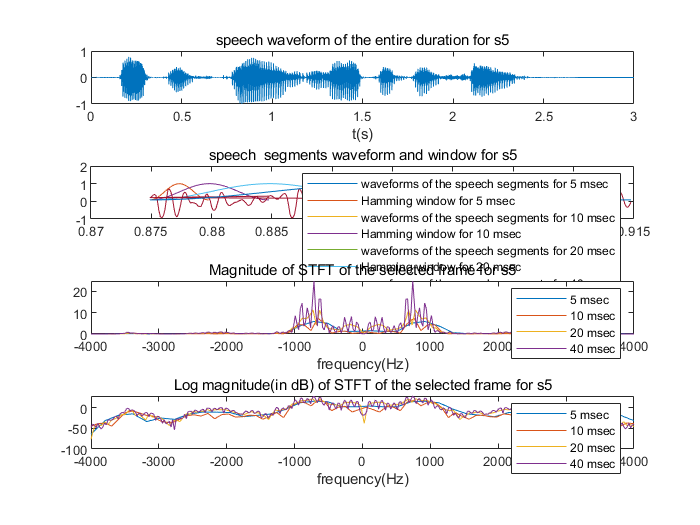

framelengths=[5 10 20 40];
[waveform,fs]=audioread('s5.wav');
[waveform,t,ham_matrix,frames_ham,frames_ham_t,magnitude_ham,magnitude_ham_w]=STSA_MultiLengths(4,'s5.wav',7000,framelengths);
figure
subplot(4,1,1);
plot(t,waveform);
xlabel('t(s)');
title('speech waveform of the entire duration for s5');

subplot(4,1,2)
sum1=0;
for j=1:length(framelengths)
      plot(frames_ham_t(1:sum1+framelengths(j)/1000*fs),frames_ham(1:sum1+framelengths(j)/1000*fs));
      hold on;
      plot(frames_ham_t(sum1+1:sum1+framelengths(j)/1000*fs),ham_matrix(sum1+1:sum1+framelengths(j)/1000*fs));
      hold on
      sum1=sum1+framelengths(j)/1000*fs;
end
legend('waveforms of the speech segments for 5 msec','Hamming window for 5 msec','waveforms of the speech segments for 10 msec','Hamming window for 10 msec','waveforms of the speech segments for 20 msec','Hamming window for 20 msec','waveforms of the speech segments for 40 msec','Hamming window for 40 msec');
xlabel('t(s)');
title('speech  segments waveform and window for s5');
ylim([-1 2]);


subplot(4,1,3)
sum2=0;
for j=1:length(framelengths)
    plot(magnitude_ham_w(sum2+1:sum2+framelengths(j)/1000*fs),magnitude_ham(sum2+1:sum2+framelengths(j)/1000*fs));
    hold on;
    sum2=sum2+framelengths(j)/1000*fs;
end
legend('5 msec','10 msec','20 msec','40 msec');
xlabel('frequency(Hz)');
title('Magnitude of STFT of the selected frame for s5');

subplot(4,1,4)
sum3=0;
for j=1:length(framelengths)
    plot(magnitude_ham_w(sum3+1:sum3+framelengths(j)/1000*fs),mag2db(magnitude_ham(sum3+1:sum3+framelengths(j)/1000*fs)));
    hold on;
    sum3=sum3+framelengths(j)/1000*fs;
end
legend('5 msec','10 msec','20 msec','40 msec');
xlabel('frequency(Hz)');
title('Log magnitude(in dB) of STFT of the selected frame for s5');

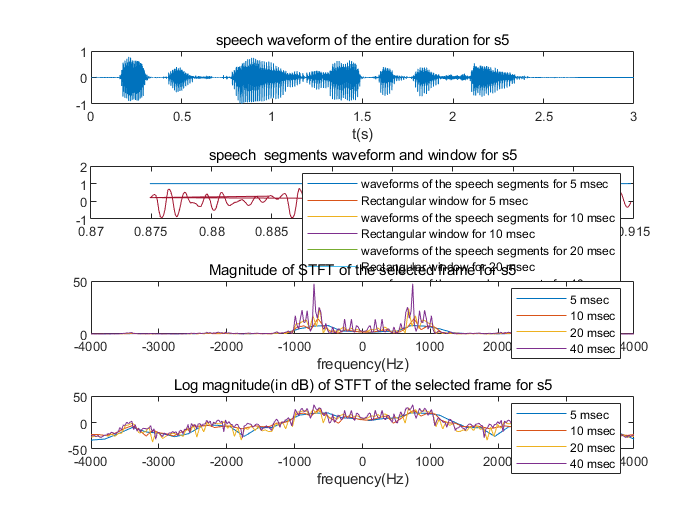



[waveform2,t2,rectangular_matrix,frames_rectangular,frames_rectangular_t,magnitude_rectangular,magnitude_rectangular_w]=STSA_MultiLengths2(4,'s5.wav',7000,framelengths);
figure
subplot(4,1,1);
plot(t2,waveform2);
xlabel('t(s)');
title('speech waveform of the entire duration for s5');

subplot(4,1,2)
sum11=0;
for j=1:length(framelengths)
      plot(frames_rectangular_t(1:sum11+framelengths(j)/1000*fs),frames_rectangular(1:sum11+framelengths(j)/1000*fs));
      hold on;
      plot(frames_rectangular_t(sum11+1:sum11+framelengths(j)/1000*fs),rectangular_matrix(sum11+1:sum11+framelengths(j)/1000*fs));
      hold on
      sum11=sum11+framelengths(j)/1000*fs;
end
legend('waveforms of the speech segments for 5 msec','Rectangular window for 5 msec','waveforms of the speech segments for 10 msec','Rectangular window for 10 msec','waveforms of the speech segments for 20 msec','Rectangular window for 20 msec','waveforms of the speech segments for 40 msec','Rectangular window for 40 msec');
xlabel('t(s)');
title('speech  segments waveform and window for s5');
ylim([-1 2]);

subplot(4,1,3)
sum22=0;
for j=1:length(framelengths)
    plot(magnitude_rectangular_w(sum22+1:sum22+framelengths(j)/1000*fs),magnitude_rectangular(sum22+1:sum22+framelengths(j)/1000*fs));
    hold on;
    sum22=sum22+framelengths(j)/1000*fs;
end
legend('5 msec','10 msec','20 msec','40 msec');
xlabel('frequency(Hz)');
title('Magnitude of STFT of the selected frame for s5');

subplot(4,1,4)
sum33=0;
for j=1:length(framelengths)
    plot(magnitude_rectangular_w(sum33+1:sum33+framelengths(j)/1000*fs),mag2db(magnitude_rectangular(sum33+1:sum33+framelengths(j)/1000*fs)));
    hold on;
    sum33=sum33+framelengths(j)/1000*fs;
end
legend('5 msec','10 msec','20 msec','40 msec');
xlabel('frequency(Hz)');
title('Log magnitude(in dB) of STFT of the selected frame for s5');